% Mathematical Models and Methods for Image Processing
% Giacomo Boracchi, Diego Carrera
% May 2022
%
% Politecnico di Milano
% giacomo.boracchi@polimi.it
%
seed = 1234

seed = 1234

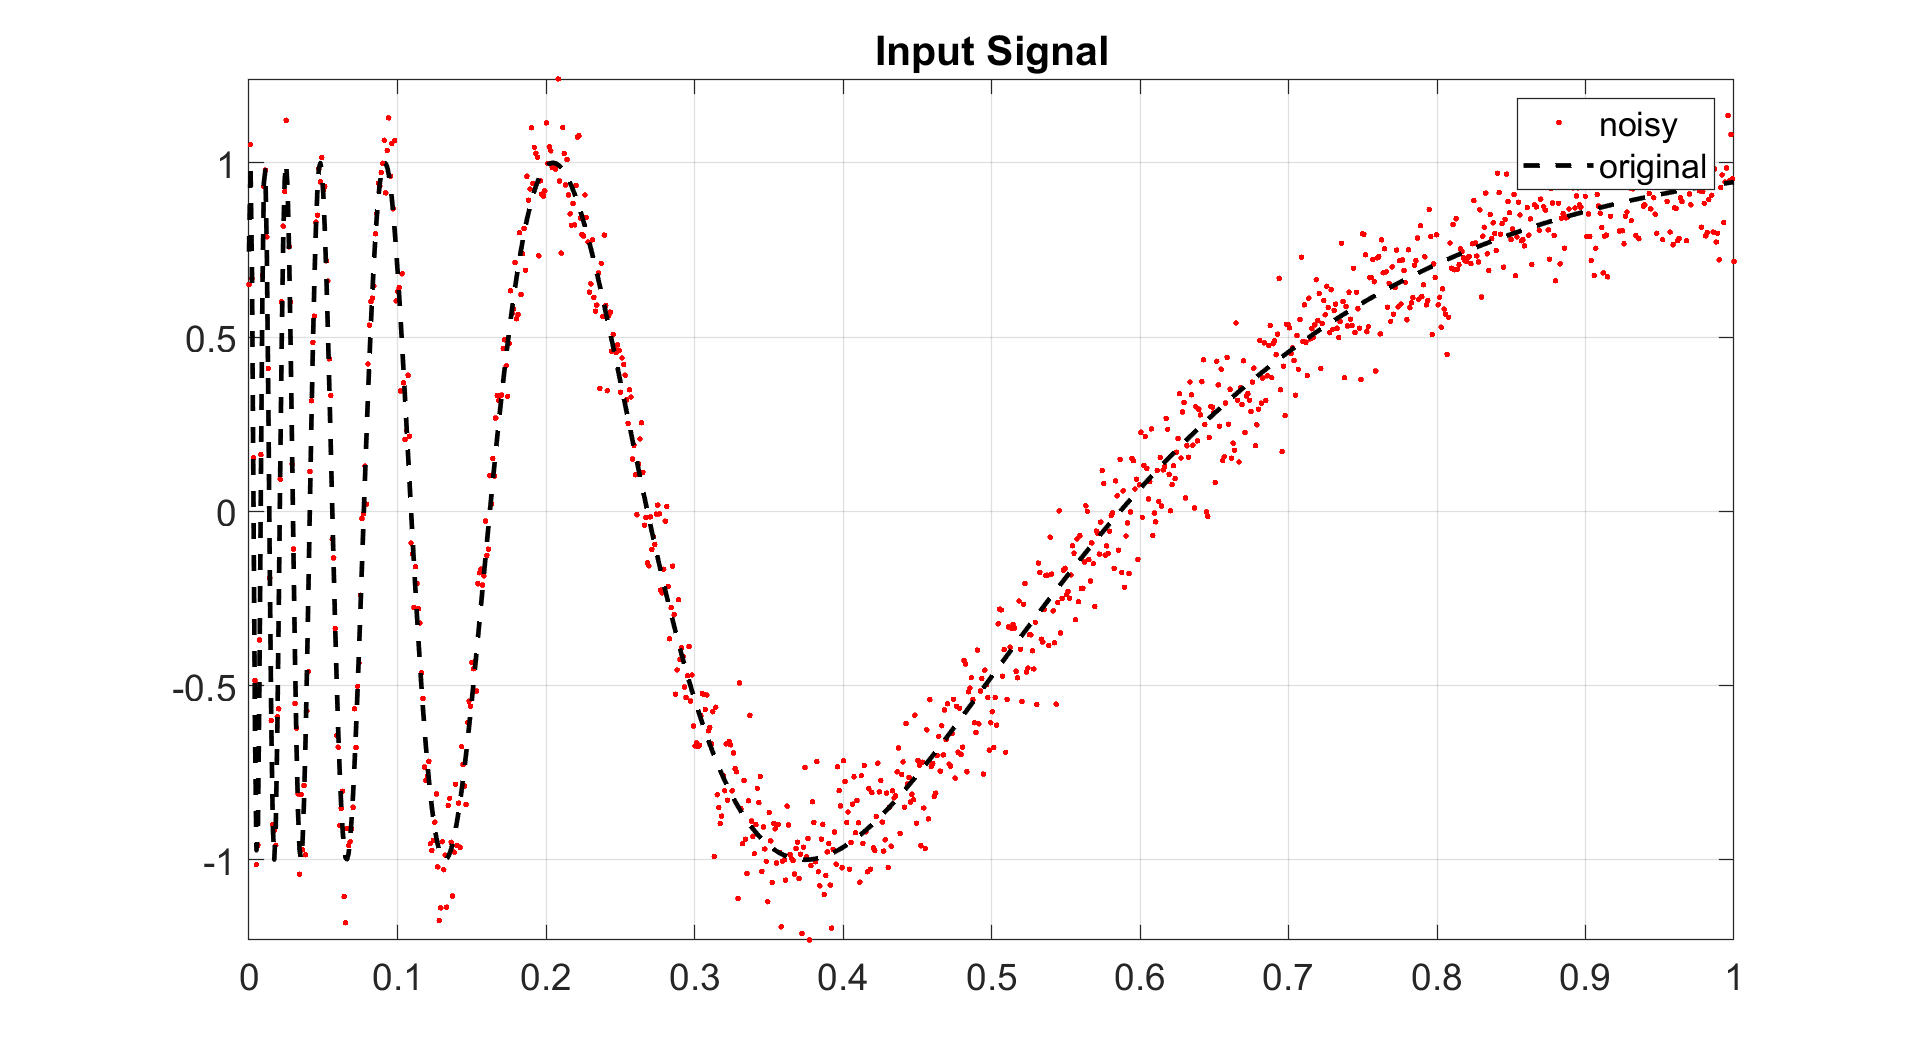

rng(seed)
clear
close all
clc

FNT_SZ = 16;

%% Set the LPA parameters

% maximum degree of polynomial used for fitting
N = 5;

% filter size
M = 7;

%% Generate Signal

% Generate the entire signal
LENGTH = 1000;
[y, ty] = get_synthetic_signal('sine', LENGTH);

% noise standard deviation
sigma = 0.1;

% noisy signal 
s = y + sigma*randn(size(y));

figure(2), 
plot(ty, s, 'r.');
hold on
plot(ty, y, 'k--', 'LineWidth', 2);
hold off
grid on
axis tight
set(gca,'FontSize', FNT_SZ)
legend('noisy', 'original');
title('Input Signal')
set(gcf, 'Position', [ 103 1 1574 867])

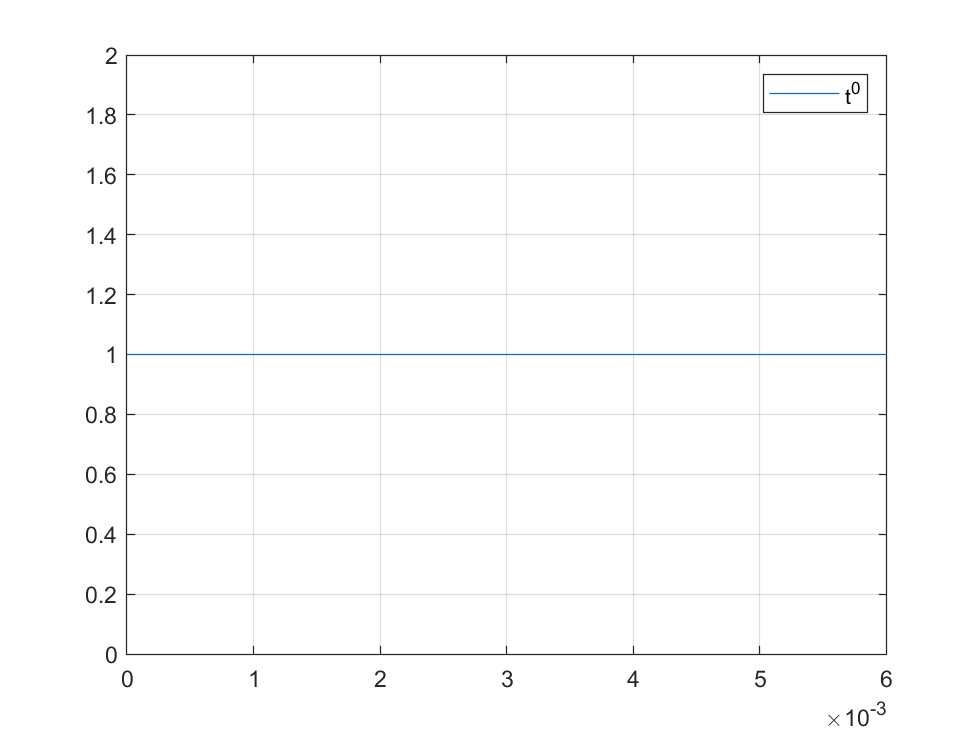

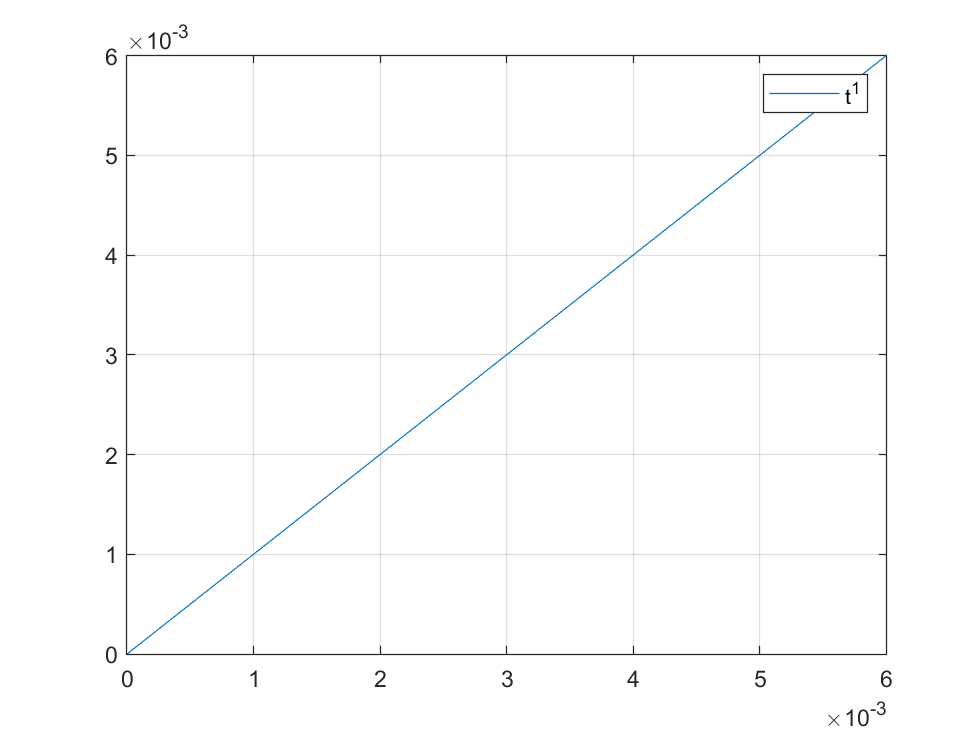

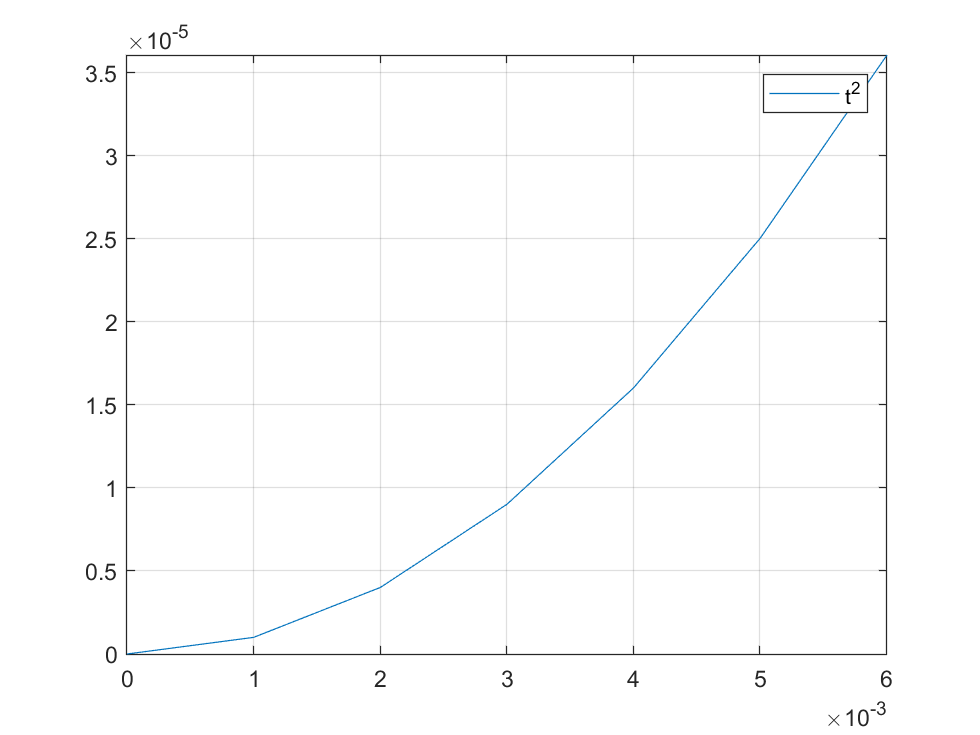

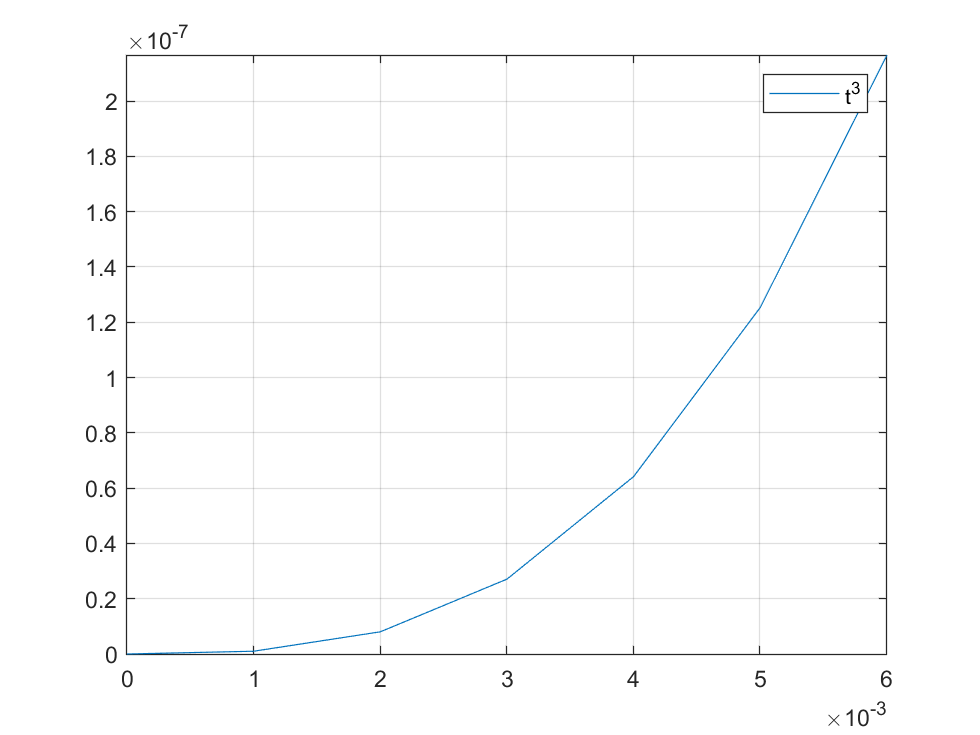

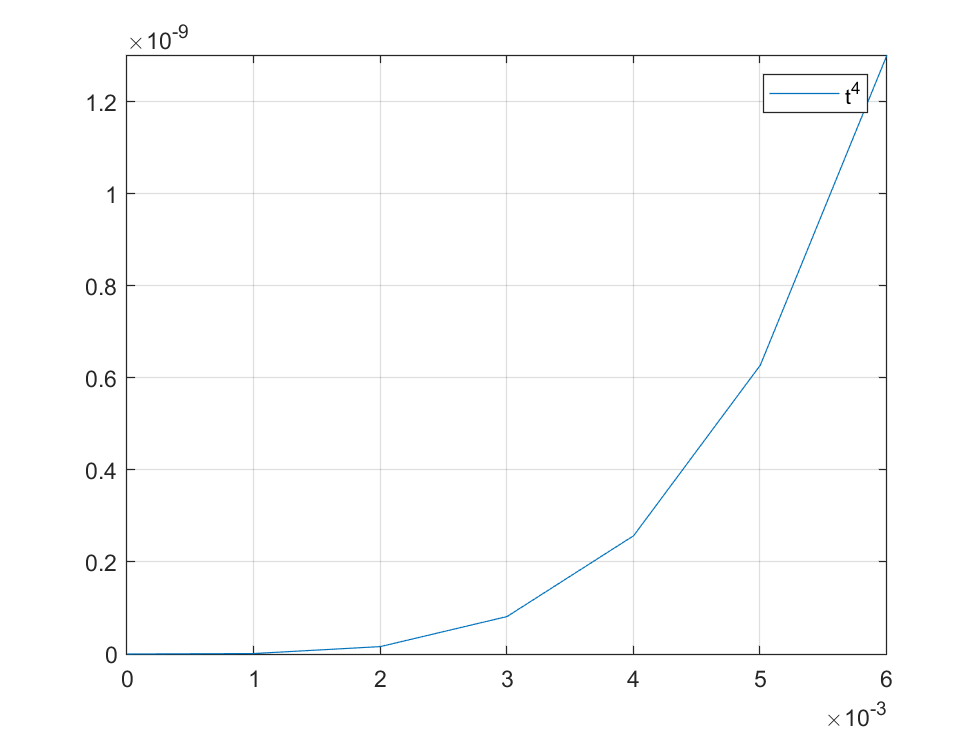

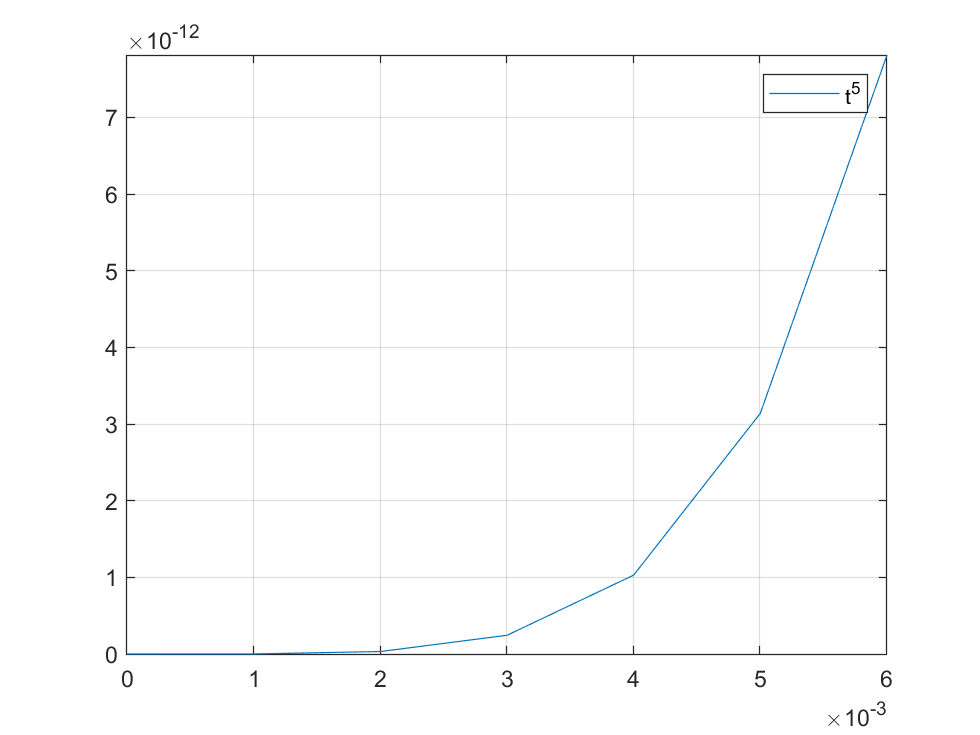

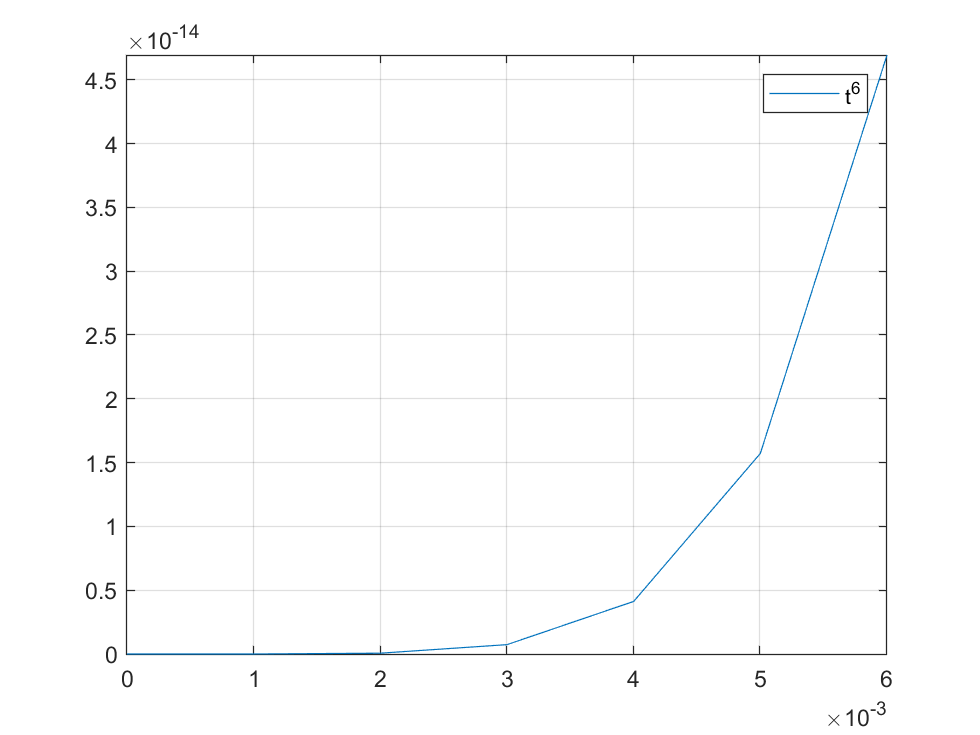

%% define the matrix T containing the polynomials sampled over the window
t = ty(1:M);
%since the time window is uniform we can take the first M times to
%construct the matrix T

T = zeros(size(t,1), N+1);
for i=1:size(T,2)+1
    T(:,i) = t.^(i-1);
end

% look at the matrix T, the columns correspond to polynomials sampled over the interval [0,1]

for ii = 1 : size(T, 2)
   figure(), cla
   plot(t, T(:, ii), 'DisplayName',sprintf('t^%d',ii - 1)) 
   axis tight
   grid on
   legend()
end

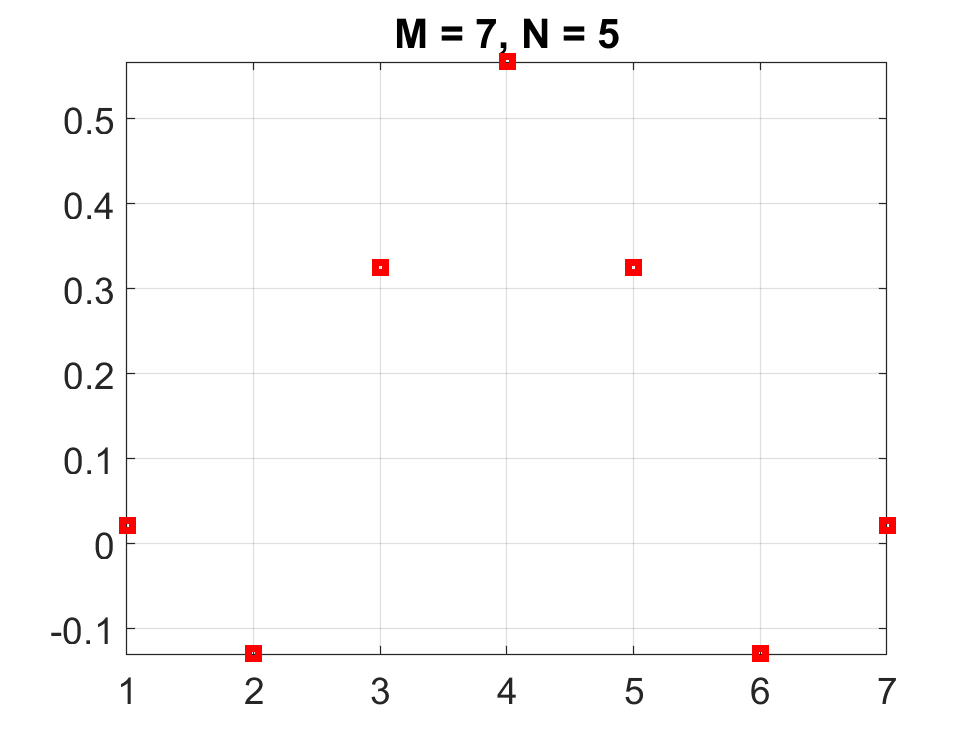

%% Construct the LPA kernel
% compute the qr decomposition of T
% since T has more rows than columns, then qr computes only the first N + 1 columns of Q and the first N + 1 rows of R.

[Q, R] = qr(T, 0);

% select the central row of Q
row = Q(round(M/2),:);

% compute the kernel
g = zeros(1,M);
for i = 1:N+1
   g = g + Q(:,i)'*row(i); 
end

% flipping, since it is used in convolution
g = flip(g);

figure(4),
plot(g, 'rs', 'LineWidth', 3), title('filter'), grid on, axis tight
set(gca,'FontSize', FNT_SZ)
title(['M = ', num2str(M), ', N = ', num2str(N)])

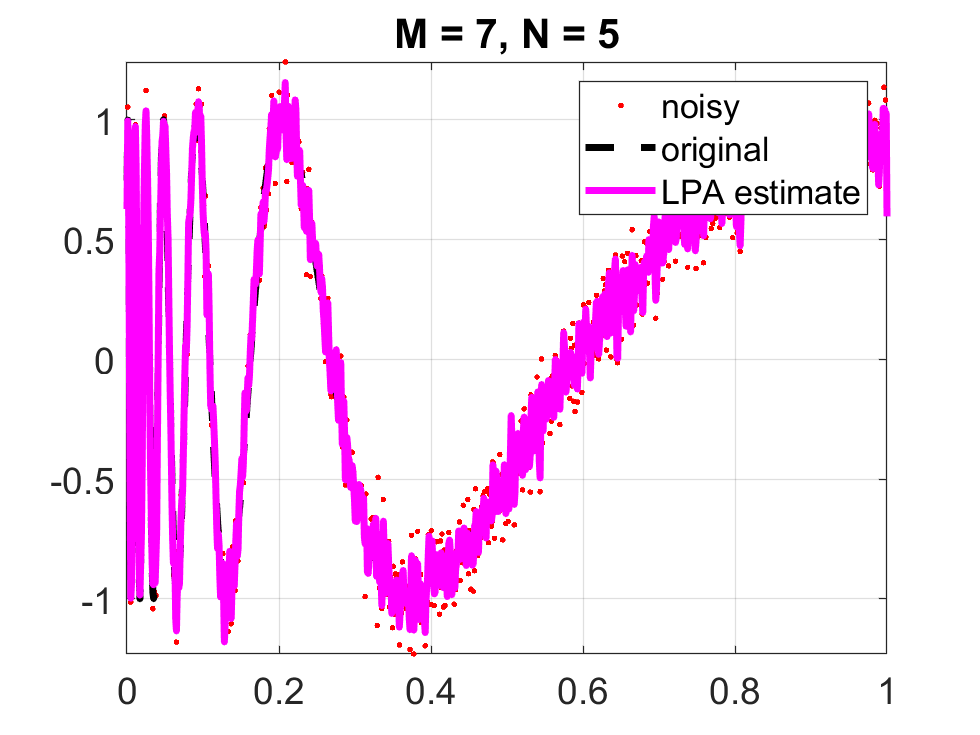

%% FILTERING
% convolution with "same" option, pads outside by introducing zeros...
% then these result in additional discontinuities

shat = conv(s,g, "same");

figure(5), 
plot(ty, s, 'r.');
hold on
plot(ty, y, 'k--', 'LineWidth', 3);
plot(ty, shat, 'm-','LineWidth', 3);
hold off
grid on
axis tight
title(['M = ', num2str(M), ', N = ', num2str(N)])
set(gca,'FontSize', FNT_SZ)
legend('noisy', 'original', 'LPA estimate');
%saveas(5, ['lez_21_A_N_', num2str(N),'_M_', num2str(M),'.png']);